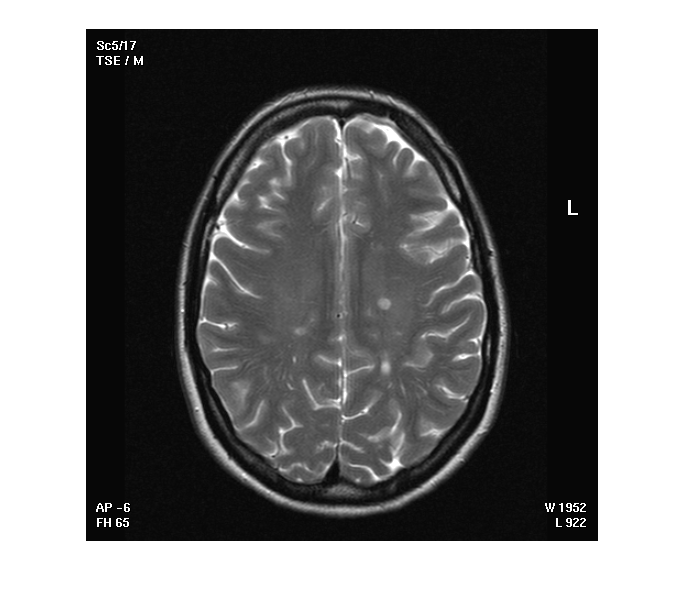

I=imread('IM_00039.TIF');
%[X, map] = dicomread('US-PAL-8-10x-echo.dcm');
%montage(X, map, 'Size', [2 5]);
imshow(I)

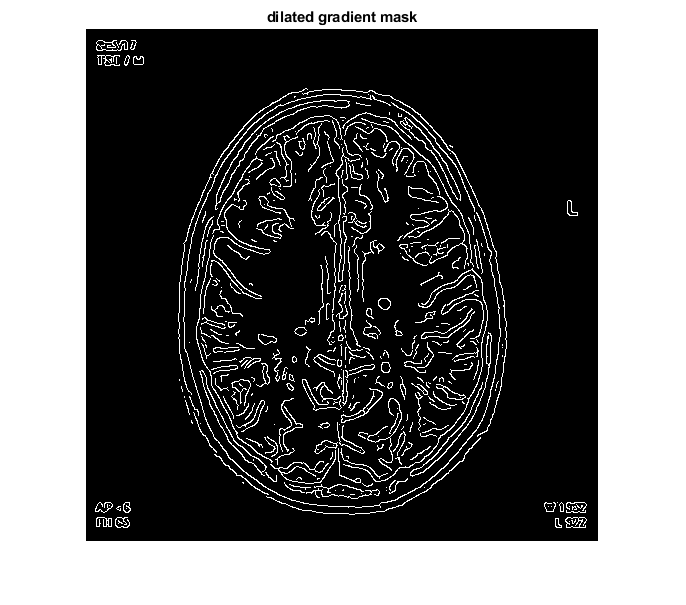

I2 = edge(I,'Canny');

se90 = strel('line', 1, 90);
se0 = strel('line', 1, 0);
%SE3 = strel('disk', 15)

BWsdil = imdilate(I2, [se90 se0]);
figure, imshow(BWsdil), title('dilated gradient mask');

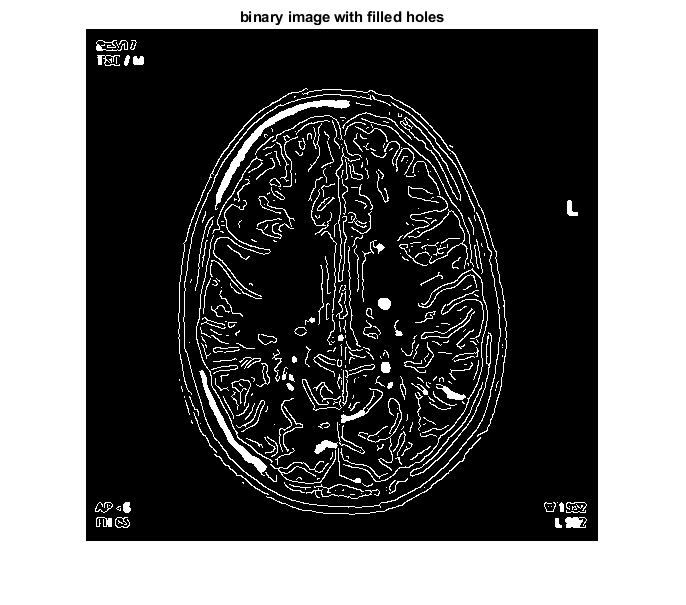

BWdfill = imfill(BWsdil, 'holes');
figure, imshow(BWdfill);
title('binary image with filled holes');

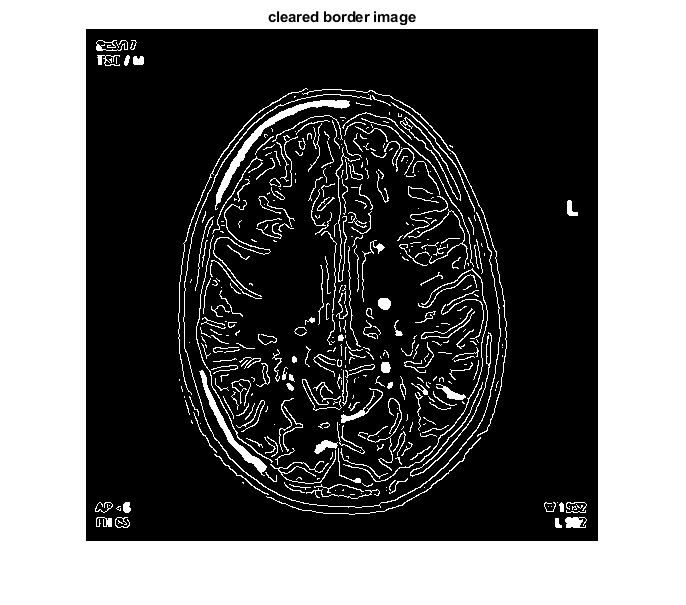

BWnobord = imclearborder(BWdfill, 4);
figure, imshow(BWnobord), title('cleared border image');

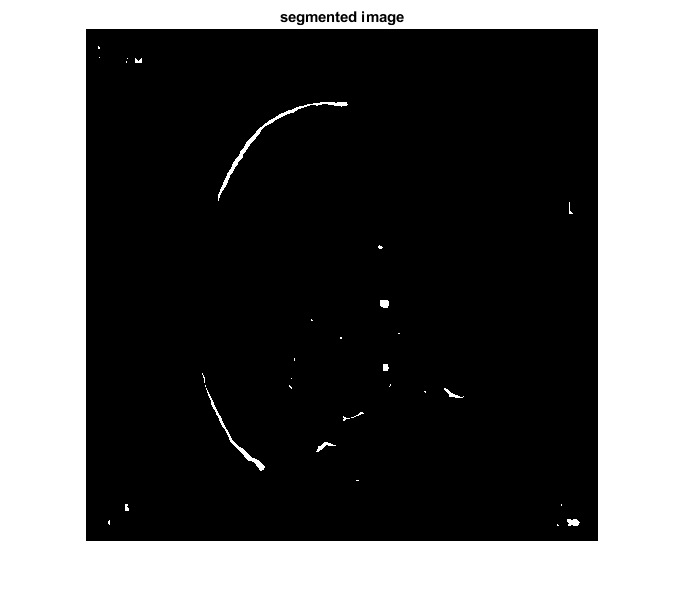

seD = strel('diamond',1);
BWfinal = imerode(BWnobord,seD);
BWfinal = imerode(BWfinal,seD);
figure, imshow(BWfinal), title('segmented image');

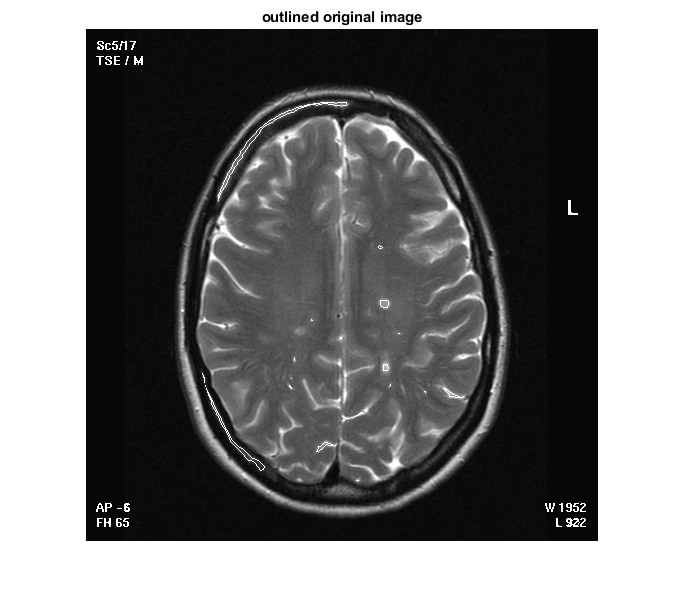

BWoutline = bwperim(BWfinal);
Segout = I; 
Segout(BWoutline) = 255; 
figure, imshow(Segout), title('outlined original image');

%Calculate two threshold levels.
thresh = multithresh(Segout,2);

%Segment the image into three levels using imquantize .
seg_I = imquantize(Segout,thresh);

%Convert segmented image into color image using label2rgb and display it.
% RGB = label2rgb(seg_I);
A = mat2gray(seg_I)

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

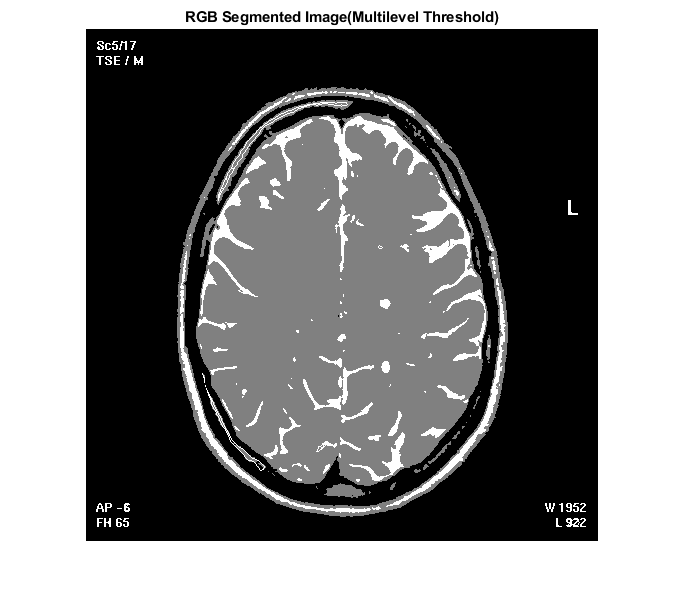

figure;
imshow(A)
axis off
title('RGB Segmented Image(Multilevel Threshold)')